**Laboratorium 5 – Całkowe przekształcenie Fouriera**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Zdefiniowanie zmiennych

clear all; close all;
syms t x f0 w w0 X_FT
f0 = 100; %Hz
w0 = 2*pi*f0;
BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

Ćwiczenie 1

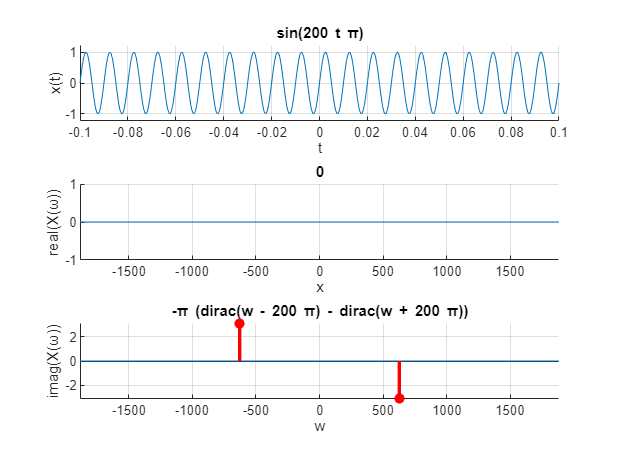

x = sin(w0*t);
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-pi pi]);

Zadanie 2a) Dla cosinusa:

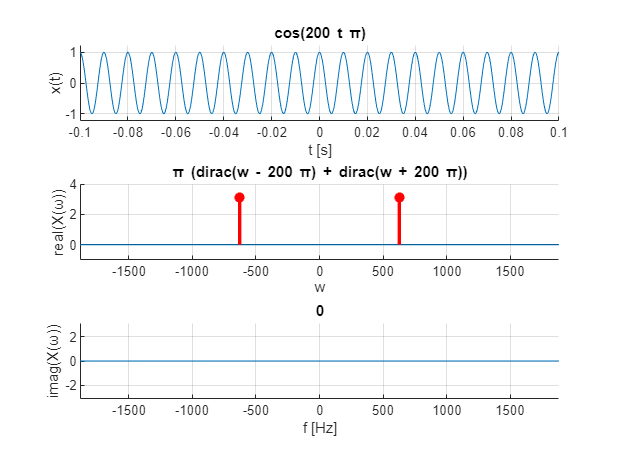

x = cos(w0*t);
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-1 4]);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-pi pi]);

Zadanie 2b) Dla sym(10):

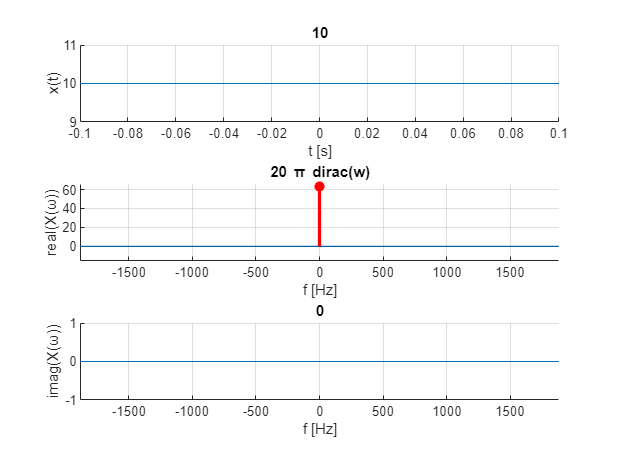

x = sym(10);
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),20*pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-5*pi 21*pi]);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]');

Zadanie 2c) Dla skoku jednostkowego rownego 1:

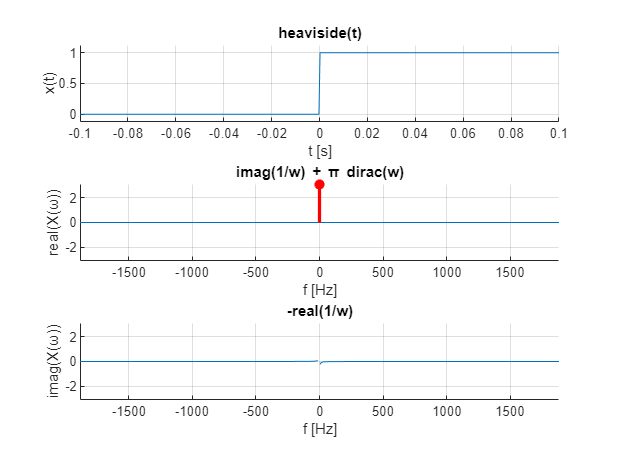

x = heaviside(t);
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
stem(0, pi*sign(1), 'r*', "LineWidth", 2);
xlabel('f [Hz]'); 
ylim([-pi pi]);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-pi pi]);

Zadanie 2d) Dla impulsu prostokatnego o amplitudzie 1 oraz czasie trwania Ti = 2/ fo:

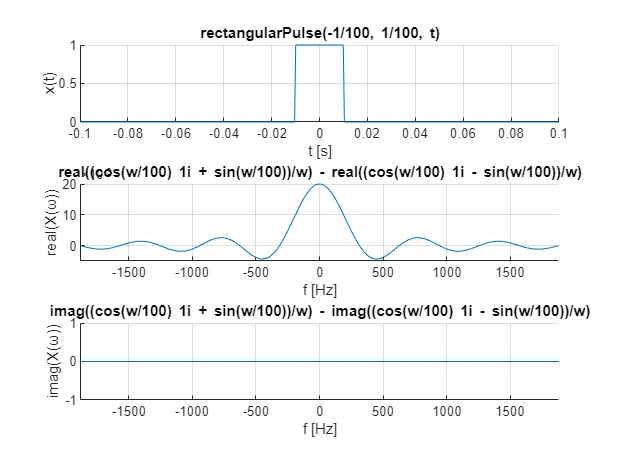

x = rectangularPulse(-1/f0, 1/f0, t); 
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-0.005 0.020]);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 

Zadanie 2e) Dla impulsu trojkatnego (symetrycznego) o amplitudzie 1 oraz czasie trwania Ti = 2/f0:

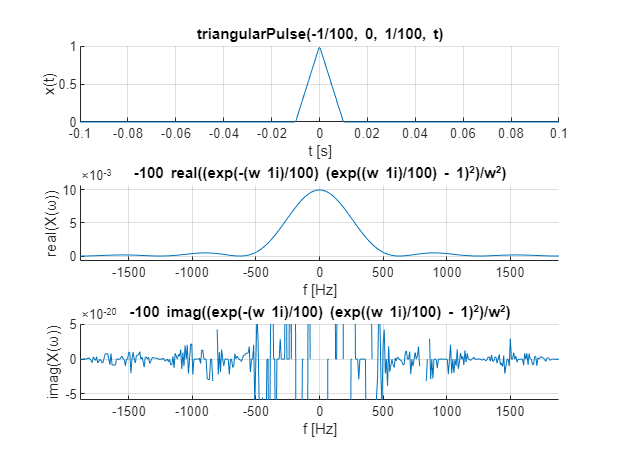

x = triangularPulse(-1/f0, 1/f0, t);
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(0, pi*sign(1), 'r*', "LineWidth", 2);
xlabel('f [Hz]');


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 

Każdy przykład z tego zadania opierał się na kodzie z ćwiczenia 1 (Kod podany w konspekcie). Zmieniane były jedynie linijki definiujące sygnał wejściowy oraz te odpowiadające za wysokość impulsów na wykresach („ręczne” skalowanie było konieczne, ponieważ funkcja ezplot nie wyświetla dystrybucji poprawnie).

Zadanie domowe ZD1

Sporządzenie wykresów gęstości widmowej amplitudy oraz fazy dla funkcji sinus i cosinus a następnie porównanie ich:

1) Dla sinusa

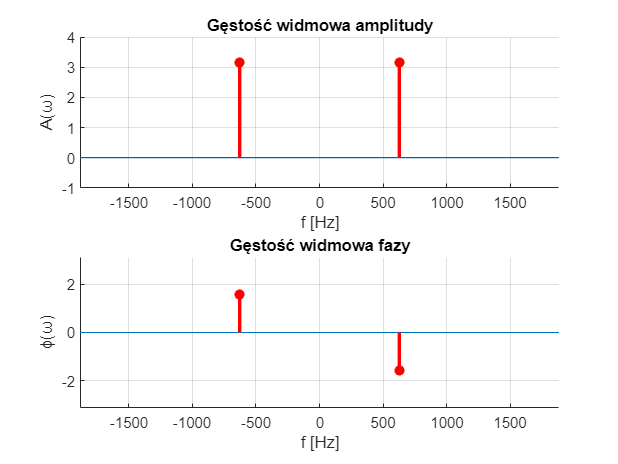

x = sin(w0*t); 
X_FT = fourier(x); 
A = abs(X_FT);       % gestosc widmowa amplitudy 
fi = angle(X_FT);    % gestosc widmowa fazy

figure
subplot(2,1,1); hold on; grid on;
ezplot(A, BND_w);
v_num = subs(A, w, w_SMP);
n = find(abs(v_num)==inf);
stem(w_SMP(n),pi*sign(v_num(n)),'r*',"LineWidth",2);
xlabel('f [Hz]'); 
ylabel('A(\omega)'); 
title('Gęstość widmowa amplitudy'); 
ylim([-1 4]);


subplot(2,1,2); hold on; grid on;
ezplot(fi, BND_w);
v_num = subs(fi, w, w_SMP);
n = find(abs(v_num)==pi/2);
stem(w_SMP(n),pi/2*sign(v_num(n)),'r*',"LineWidth",2);
xlabel('f [Hz]'); 
ylabel('\phi(\omega)'); 
title('Gęstość widmowa fazy'); 
ylim([-pi pi]);

2) Dla cosinusa

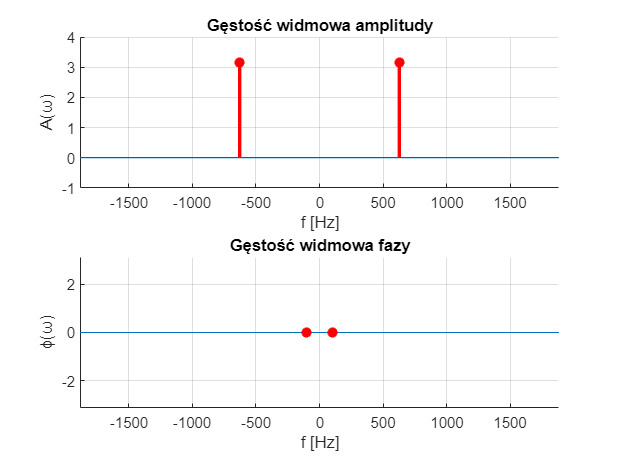

x = cos(w0*t); 
X_FT = fourier(x); 
A = abs(X_FT);       % gestosc widmowa amplitudy 
fi = angle(X_FT);    % gestosc widmowa fazy

figure
subplot(2,1,1); hold on; grid on;
ezplot(A, BND_w);
v_num = subs(A, w, w_SMP);
n = find(abs(v_num)==inf);
stem(w_SMP(n),pi*sign(v_num(n)),'r*',"LineWidth",2);
xlabel('f [Hz]'); 
ylabel('A(\omega)'); 
title('Gęstość widmowa amplitudy'); 
ylim([-1 4]);


subplot(2,1,2); hold on; grid on;
ezplot(sym(0), BND_w);
%v_num = subs(fi, w, w_SMP); 
%n = find(abs(v_num)==pi/2);
%stem(w_SMP(n),pi/2*sign(v_num(n)),'r*',"LineWidth",2);
stem(-100, 0, 'r*', 'LineWidth', 2); hold on;
stem(100, 0, 'r*', 'LineWidth', 2);
xlabel('f [Hz]');
ylabel('\phi(\omega)'); 
title('Gęstość widmowa fazy'); 
ylim([-pi pi]);

Można zauważyć, że gęstość widmowa amplitudy dla obu funkcji jest taka sama. Dzieje się tak, ponieważ impulsy Diraca mają tą samą amplitudę dla tych samych częstotliwości.

Dla sinusa występują one jako liczby urojone, dlatego ich kąt wynosi π/2 oraz -π/2. Natomiast dla cosinusa są one rzeczywiste, dlatego faza jest zerem.

Zadanie 3

Modulacja sygnału cos(ω0t) przebiegiem sinusoidalnym o częstotliwości 10-krotnie mniejszej, amplitudzie 1 i głębokości modulacji m = 0,5

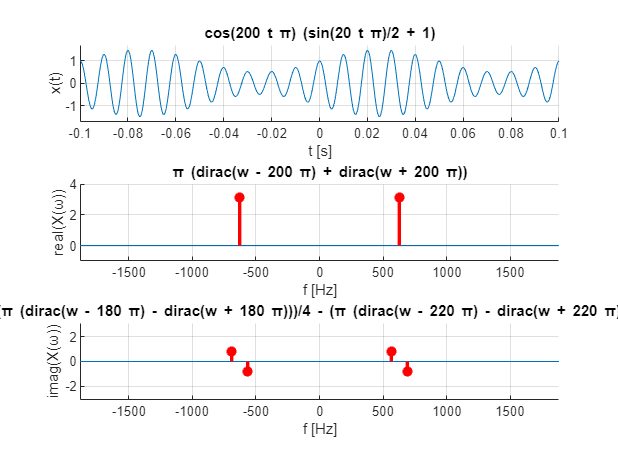

A = 1; 
m = 0.5; 
f_10 = w0/10; 
x = (A + m*sin(f_10*t))*cos(w0*t); 
X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2); 
xlabel('t [s]');


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-1 4]);


subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),(pi/4)*sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('f [Hz]'); 
ylim([-pi pi]);

Zadanie domowe ZD2

Porównanie mocy sygnału nośnego z mocą wynikowego sygnału zmodulowanego.

Moc sygnału nośnego cos(ω0t):


$$P\left(\cos \left.{\left(w0*t\right)}\right)=P{\left(\cos {\left(200\pi *t\right)}\right)}=50*\int_{-0.01}^{0.01} {{\left|\mathrm{c}\mathrm{o}\mathrm{s}\left(200\pi *t\right.\right|}}^2 dt=0.5$$


Moc sygnału modulowanego cos(w0t)*(1+0.5*sin(w0/10*t)):


$$P{\left(\cos {\left(wo*t\right)}*{\left(1+0.5\sin {\left(\frac{w0}{10}*t\right)}\right)}\right)}=0.5*\int_{-0.1}^{0.1} \cos {\left(wo*t\right)}*{{\left(1+0.5\sin {\left(\frac{w0}{10}*t\right)}\right)}}^2 dt=0.5625$$


close all, clear all;
syms t m 
w0 = 200*pi;
T = 0.1;
x = cos(w0*t) + m*cos(w0*t)*sin(w0/10*t);
P = (1/(2*T))*int((x)^2, t, -T, T)

$$P = \frac{m^{2}}{4}+\frac{1}{2}$$

W tym konkretnym przypadku można zauwazyć, że wzór na moc sygnału modulowanego wyraża się:


$$P\left(m\right)=P_{\textrm{sygna\lu}\;\textrm{nośnego}} +\;\frac{m^2 }{4}$$


Gdzie ***m*** to głębokość modulacji.

Zadanie 4

Wyznaczenie sygnału cos(w0*t) okienkowanego dla funkcji okna postaci:

a) sygnału prostoknątnego

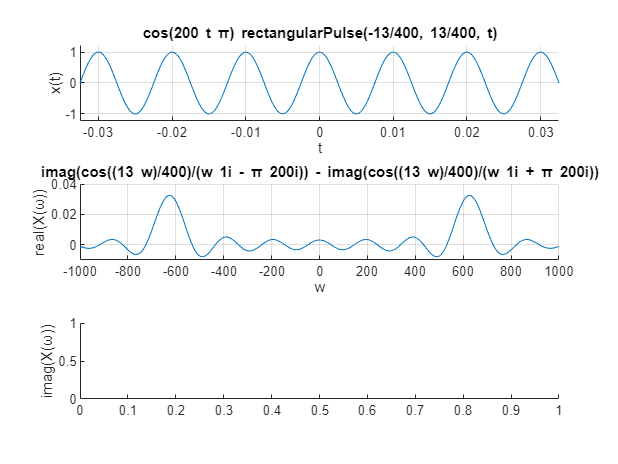

clear all; close all;
syms t x f0 w w0 X_FT

f0 = 100; %Hz
w0 = 2*pi*f0;
To = 6.5/f0;

BND_t = [-6.5/(2*f0); 6.5/(2*f0)]; %6.5 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];

syg_prost = rectangularPulse(-To/2, To/2, t);
x = cos(w0*t); 
x_prost = x*syg_prost; 
X_FT = fourier(x_prost);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x_prost, BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-0.01 0.04]) 
xlim([-1000 1000])

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on

%ezplot(imag(X_FT), BND_w); hold on; grid on
%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

b) dla impulsu trójkątnego

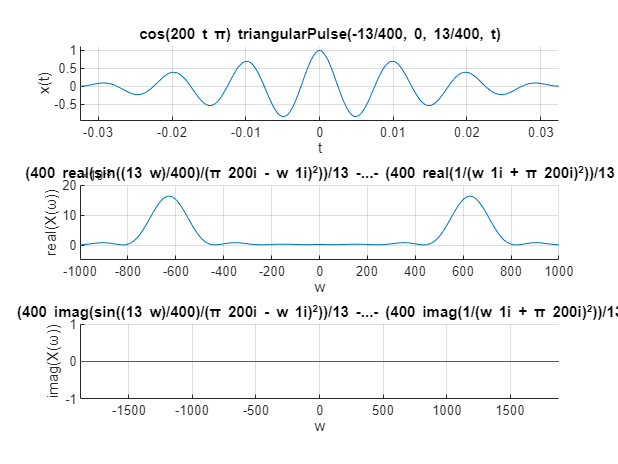

syg_trojk = triangularPulse(-To/2, To/2, t); 
x = cos(w0*t); 
x_trojk = x*syg_trojk; 
X_FT = fourier(x_trojk);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x_trojk, BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlim([-1000 1000]); 
ylim([-0.005 0.020]);

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

c) dla krzywej Gaussa

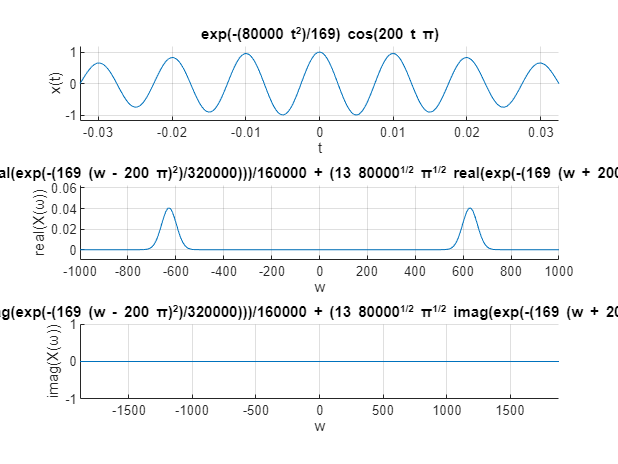

c = To/2; 
syg_Gauss = exp(-t.^2/(2*c.^2)); 
x = cos(w0*t); 
x_Gauss = x*syg_Gauss; 
X_FT = fourier(x_Gauss);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x_Gauss, BND_t); hold on; grid on;
%v_num = subs(x, t, t_SMP);
%n = find(abs(v_num) == inf); % plot dirac (inf)
%stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
%v_num = subs(real(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf); % plot dirac (inf)
%stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
ylim([-0.01 2*pi*0.01]) 
xlim([-1000 1000])

subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on

%v_num = subs(imag(X_FT), w, w_SMP);
%n = find( abs(v_num) == inf ); % plot dirac (inf)
%stem(w_SMP(n),pi*sign(v_num(n)),'r*', 'LineWidth', 2);

Okno prostokątne przepuszcza sygnał wejściowy w niezmienionym stanie w obrębie okna, poza nim blokując go całkowicie.

Okno trójkątne wzmacnia sygnał liniowo tym bardziej, im bliżej jest on środka okna.

Z zaprezentowanych powyżej funkcji okna, najelpszym wydaje się okienkowanie za pomocą krzywej Gaussa, ponieważ w porównaniu do innych sposobów najefektywniej wytłumia zbędne częstości kołowe i najlepiej eksponuje te, które są w centrum zainteresowania to znaczy nabliżej częstości kołowej sinsua nieokienkowanego. 

Zadanie domowe ZD3

Gęstość widmowa amplitudy:

a) dla sygnału prostokątnego

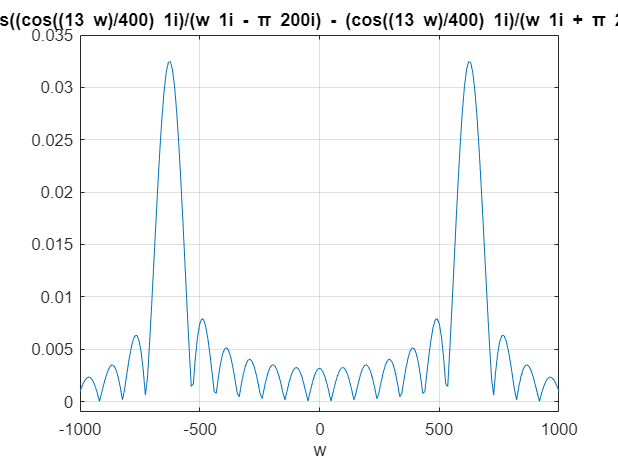

X_FT = fourier(x_prost); 
A = abs(X_FT); 
figure 
ezplot(A, BND_w); 
grid on; 
xlim([-1000 1000]); 
ylim([-0.001, 0.035]);

b) dla sygnału trójkątnego

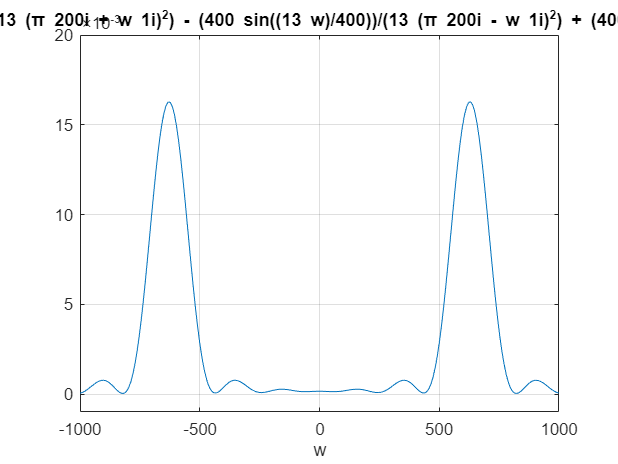

X_FT = fourier(x_trojk); 
A = abs(X_FT);
figure 
ezplot(A, BND_w); 
grid on; 
xlim([-1000 1000]); 
ylim([-0.001, 0.020]);

c) dla krzywej Gaussa

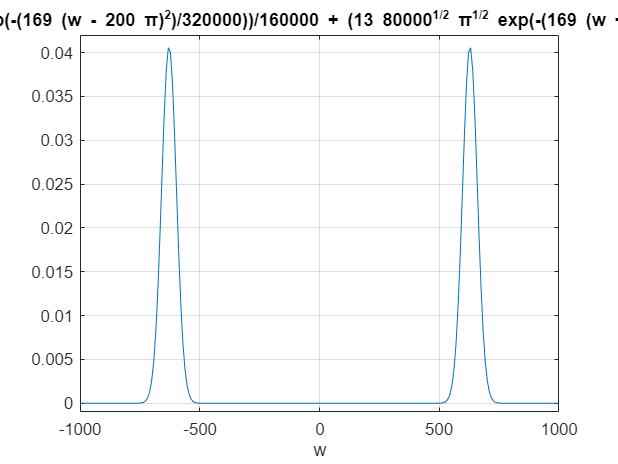

X_FT = fourier(x_Gauss); 
A = abs(X_FT); 
figure 
ezplot(A, BND_w);
grid on; 
xlim([-1000 1000]); 
ylim([-0.001, 0.042]);

Wykresy gęstości widmowej sygnałów okienkowanych znacząco różnią się od wykresu nieokienkowanego cosinusa – nie posiadają impulsów Diraca, lecz cały zakres składowych częstotliwości.